% Clear old vars
clear
% Connect to raspi
%rpi = raspi()

% Note: use webcam function instead if using a USB camera
cam = Camera()

cam =   Camera with properties:

           cam: [1×1 webcam]
    intrinsics: [1×1 cameraIntrinsics]
       tagSize: 0.1650


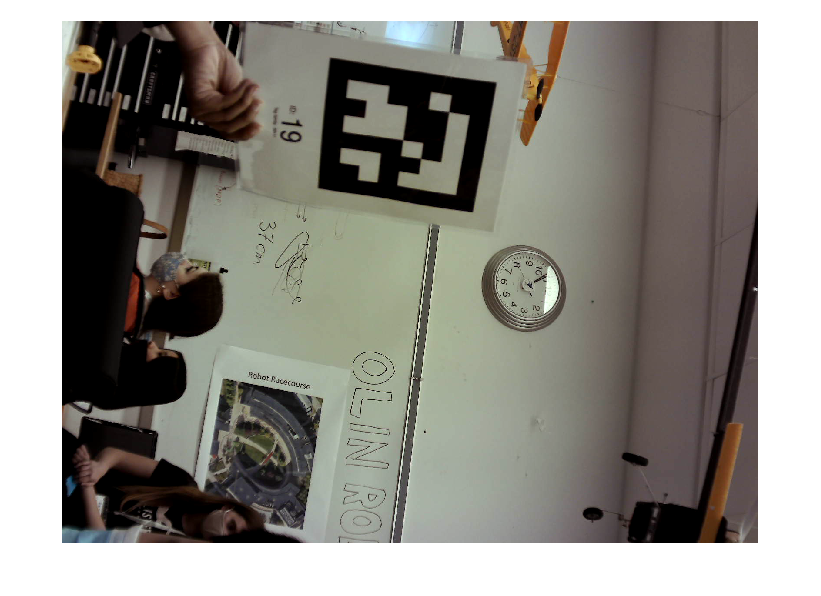

% Flush camera buffer
for v = 0:1:5
    % Take a photo using the camera
   I = snapshot(cam.cam);
end

% Display image
figure, imshow(I)

Detected Tag ID, Family: 19, tag36h11
   1.0e+03 *

    0.6156    0.0855
    0.5881    0.3847
    0.9458    0.4417
    1.0005    0.1444



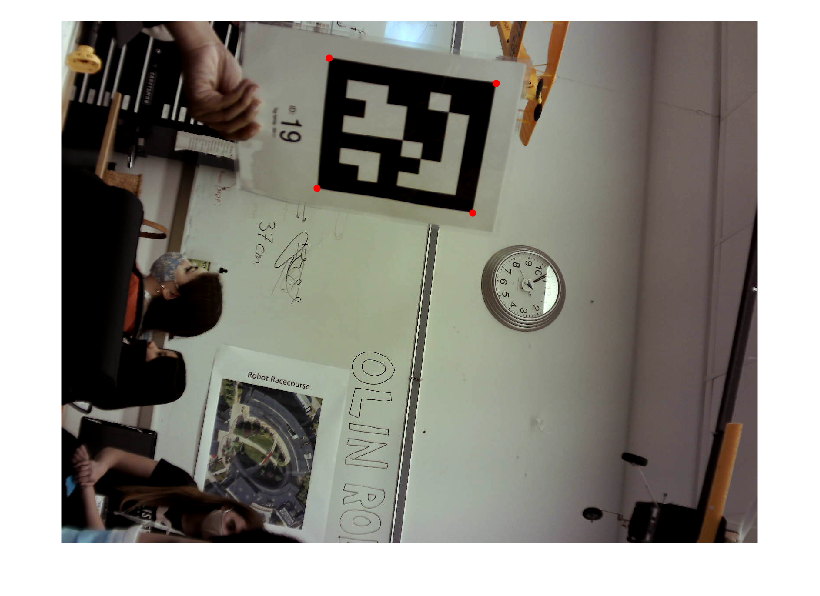

centers =   787.4730  264.0840


ids = 19

%I = imread("ReadAprilTagsInImageExample_01.png");
[centers, ids] = detectAprilTags(I, true) % Change to false to suppress output

    function [centers, ids] = detectAprilTags(image, display)
    tagFamily = ["tag36h11"];
    
    [ids,loc,detectedFamily] = readAprilTag(image, tagFamily);
    
    centers = zeros(length(ids), 2);
    
    for idx = 1:length(ids)
        % Compute center of tag
        center = mean(loc(:,:,idx));

        % Add 2D center of tag to list
        centers(idx,:) = center;
        
        if display
            % Display the ID and tag family
            disp("Detected Tag ID, Family: " + ids(idx) + ", " ...
                + detectedFamily{idx})
            disp(loc)
            
            % Insert markers to indicate the locations
            markerRadius = 8;
            numCorners = size(loc,1);
            markerPosition = [loc(:,:,idx),repmat(markerRadius,numCorners,1)];
            image = insertShape(image,"FilledCircle",markerPosition,"Color","red","Opacity",1);
        end
    end
    
    if display
        imshow(image);
    end
end